# AAE 340 HW 12 MATLAB CODE 

## Problem 2

## Author: Tomoki Koike 

clear all;
close all;
clc;

% Defining the constants
% Mass [kg]
m = 2000;  
% PMOI [kg-m^2]
Ix = 3012; 
Iy = 2761;
Iz = 4627;
% Torque [N-m]
Mx = -0.5669;
My = 0.4757;
Mz = 13;

% Defining the ICs for the ode45
% Angular velocity [rad/s]
wx0 = 0;
wy0 = 0;
wz0 = 3*2*pi/60;
% Angles [rad]
phi0 = 0;
theta0 = -pi/2;
psi0 = 0;
% Initial Conditions 
ICs = [wx0, wy0, wz0, phi0, theta0, psi0];

% Solving ode45
tspan = 0:0.001:120;
options = odeset('RelTol',1e-12, 'AbsTol',1e-12);
[t, Xs] = ode45(@(t, x) EOM(t, x, Ix, Iy, Iz,...
    Mx, My, Mz), tspan, ICs, options);
% Setting variables to the obtained results
wx = Xs(:,1);
wy = Xs(:,2);
wz = Xs(:,3);
phi = Xs(:,4);
theta = Xs(:,5);
psi = Xs(:,6);

% Defining the angular momentum [kg-m^2/s]
Hx = Ix*wx;
Hy = Iy*wy;
Hz = Iz*wz;

% Transforming the body-fixed components to intertial components 
% For the angular momentum
% The Direction cosine matrix
for i = 1:length(t)
    DCM = [(cos(psi(i))*cos(phi(i))-cos(theta(i))*sin(psi(i))*sin(phi(i))),...
        (cos(psi(i))*sin(phi(i))+cos(theta(i))*sin(psi(i))*cos(phi(i))),...
        (sin(theta(i))*sin(psi(i))); (-sin(psi(i))*cos(phi(i))...
        -cos(theta(i))*cos(psi(i))*sin(phi(i))), (-sin(psi(i))*sin(phi(i))+...
        cos(theta(i))*cos(psi(i))*cos(phi(i))), (sin(theta(i))*cos(psi(i)));...
        (sin(theta(i))*sin(phi(i))), (-sin(theta(i))*cos(phi(i))), cos(theta(i))]';
    H_inert(:,i) = DCM*[Hx(i); Hy(i); Hz(i)];
end
HX = H_inert(1,:);
HY = H_inert(2,:);
HZ = H_inert(3,:);

## <2a>

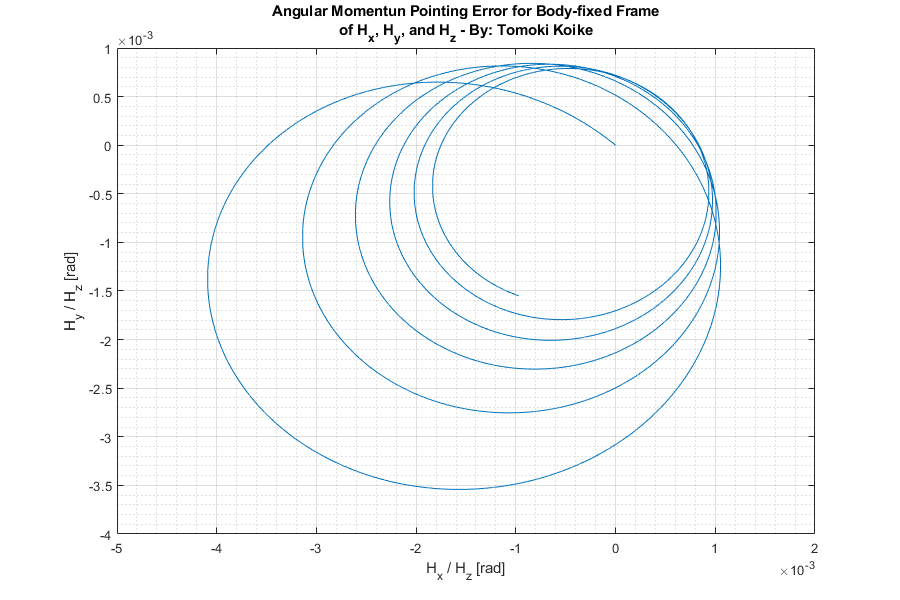

% Plotting
figure('Renderer',"painters", "Position",[10 10 900 600]);
plot(Hx./Hz, Hy./Hz)
title({'Angular Momentun Pointing Error for Body-fixed Frame', ['' ...
    'of H_x, H_y, and H_z - By: Tomoki Koike']})
xlabel('H_x / H_z [rad]')
ylabel('H_y / H_z [rad]')
grid on
grid minor
box on

## <2b>

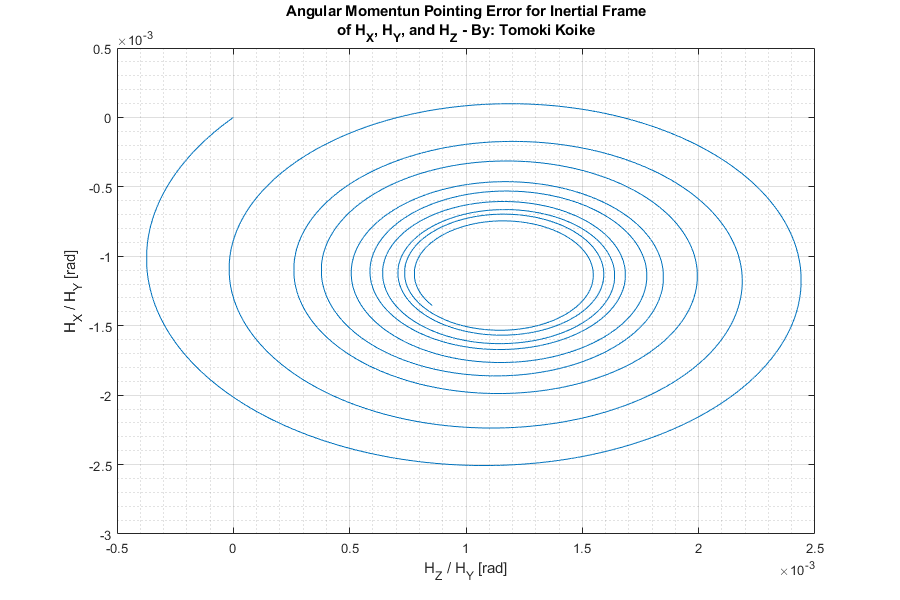

% Plotting
a = HZ./HY;
b = HX./HY;
figure('Renderer',"painters", "Position",[10 10 900 600]);
plot(HZ./HY, HX./HY)
title({'Angular Momentun Pointing Error for Inertial Frame', ['' ...
    'of H_X, H_Y, and H_Z - By: Tomoki Koike']})
xlabel('H_Z / H_Y [rad]')
ylabel('H_X / H_Y [rad]')
grid on
grid minor
box on

## Function

function dxdt = EOM(t, x, Ix, Iy, Iz, Mx, My, Mz)
    % Space State System
    wx = x(1);
    wy = x(2);
    wz = x(3);
    phi = x(4);
    theta = x(5);
    psi = x(6);
    
    dxdt(1) = (Mx - (Iz - Iy)*wy*wz)/Ix;
    dxdt(2) = (My - (Ix - Iz)*wz*wx)/Iy;
    dxdt(3) = (Mz - (Iy - Ix)*wx*wy)/Iz;
    dxdt(4) = (sin(psi)*wx + cos(psi)*wy)/sin(theta);
    dxdt(5) = cos(psi)*wx - sin(psi)*wy;
    dxdt(6) = wz - cos(theta)/sin(theta)*(sin(psi)*wx + cos(psi)*wy);
    dxdt = dxdt';
end